### Tuning PI untuk Plant Orde-1 metode Pole-Zero Cancelation

uc = 10;            % setpoint
tau = 0.4;          % konstanta waktu plant
K = 1.2;            % gain plant
actuator_max = 30; % output actuator maksimal
ts=0.1;             % waktu mantap yang diinginkan

tau_aksen_min = uc*tau/(K*actuator_max);
tau_aksen=ts/4;

if tau_aksen<tau_aksen_min
    tau_aksen = tau_aksen_min;
    ts_aktual = tau_aksen*4;
else
    ts_aktual=ts;
end

Ki = 1/(K*tau_aksen);
Kp = tau*Ki;
G=tf(K,[tau 1]);
C=tf([Kp Ki],[1 0]);
M=uc*feedback(C,G);
Gc=feedback(C*G,1);

fprintf("Kp=%f Ki=%f\n",Kp, Ki);

Kp=3.000000 Ki=7.500000


fprintf("actuator max=%f(set) %f(aktual)\n",actuator_max, stepinfo(M).SettlingMax);

actuator max=30.000000(set) 30.000000(aktual)


fprintf("ts=%f(diinginkan) %f(aktual)\n",ts, ts_aktual);

ts=0.100000(diinginkan) 0.444444(aktual)


stepinfo(Gc)

ans = struct with fields:
         RiseTime: 0.2441
    TransientTime: 0.4347
     SettlingTime: 0.4347
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 0.8136


[p,z]=pzmap(Gc)

p =    -9.0000
   -2.5000


z = -2.5000

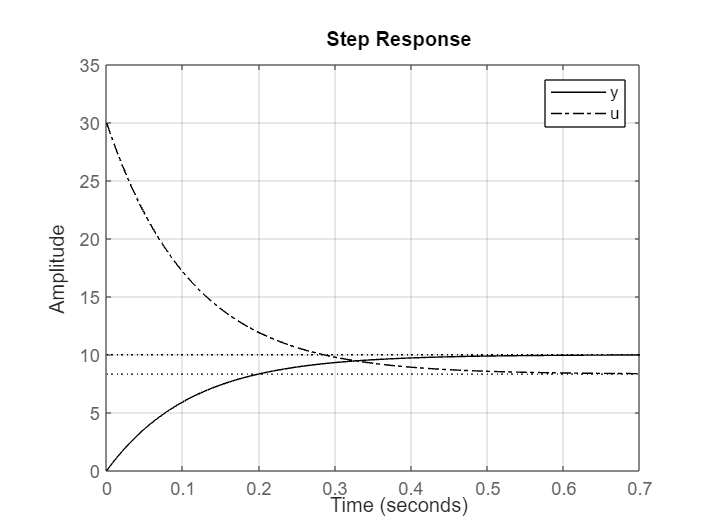

step(uc*Gc,'k-', M,'k-.');
grid on
legend('y','u')